clear; clc;

#### Ocean IOP

load("mat data\Ocean_IOP_Jerlov.mat")
load('mat data\Kd_database.mat')
typename = {'JerlovI','JerlovIA','JerlovIB','JerlovII','JerlovIII','Jerlov1C','Jerlov3C','Jerlov5C'};

#### Plot all

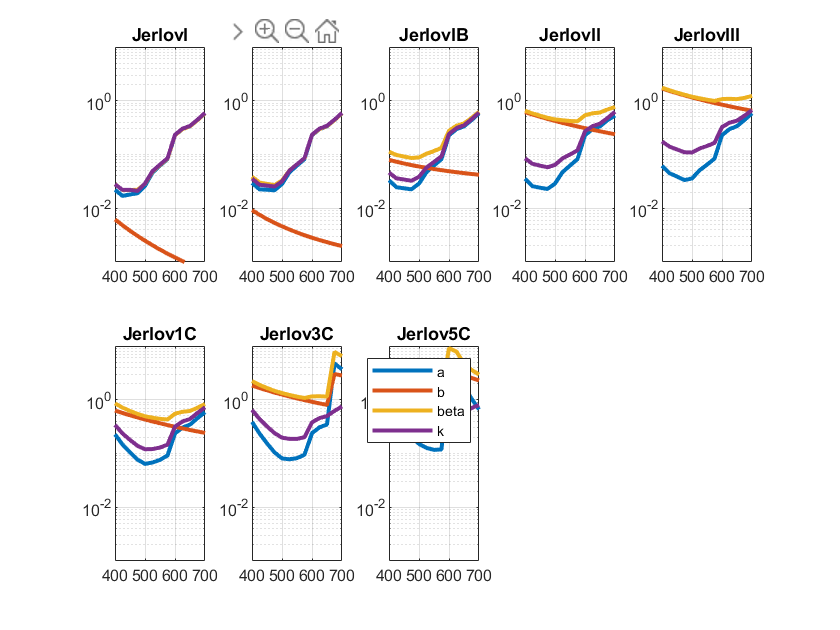

figure
x = 400:25:700;
for i = 1:8
    subplot(2,5,i)
    plot (x, [a_Jerlov(5:end,i) b_Jerlov(5:end,i) beta_Jerlov(5:end,i) Kd_Jerlov(5:end,i)],'LineWidth',2);
    hold on
    grid on
    set(gca, 'YScale', 'log')
    ylim([10^-3 10])
    yticks auto
    title(typename{i})

end
legend('a','b','beta', 'k')
set(gcf,'Visible','on')

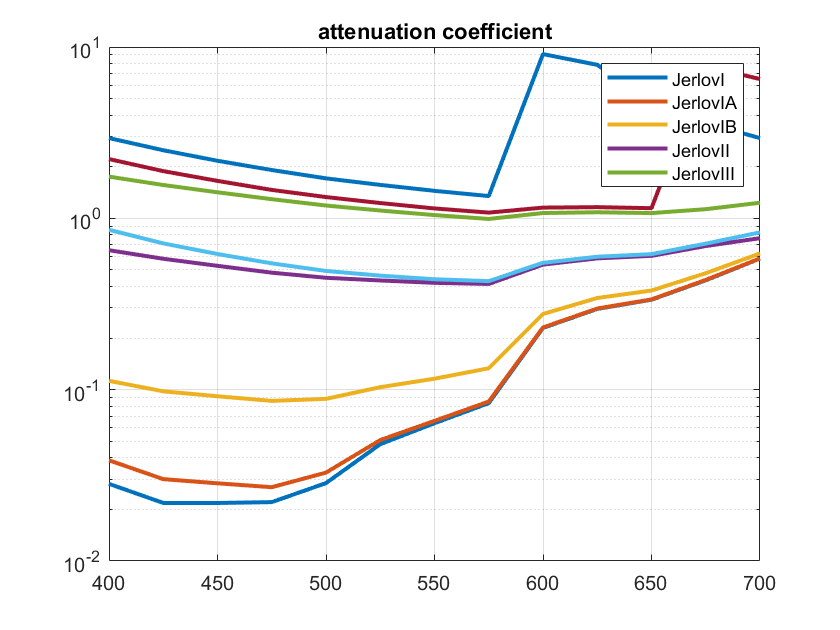

figure
x = 400:25:700;
for i = 1:8

    plot (x, beta_Jerlov(5:end,i) ,'LineWidth',2);
    hold on
    grid on
    set(gca, 'YScale', 'log')
    
    title('attenuation coefficient')
end
legend(typename{1:5})
set(gcf,'Visible','on')